clear;
mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122


[L1,L2,L3,L4x,L4y,L5x,L5y] = LibrationPoints(mu);
L1 = 0.8369151324

L1 = 0.8369

L2  = 1.1556821603

L2 = 1.1557

Ax=0.0420;
%get an aprox. of the initial points lyapunov orbit
%[Xguess, Vy_guess ] = initialPositionLyapunov(mu,L1,Ax)
Xguess = 0.7949

Xguess = 0.7949

Vy_guess = 0.3822

Vy_guess = 0.3822

limit_criteria = -0.0561

Iteration counter: 1


limit_criteria = -0.0238

Iteration counter: 2


limit_criteria = -0.0088

Iteration counter: 3


limit_criteria = -0.0030

Iteration counter: 4


limit_criteria = -9.9141e-04

Iteration counter: 5


limit_criteria = -3.2255e-04

Iteration counter: 6


limit_criteria = -1.0450e-04

Iteration counter: 7


limit_criteria = -3.3806e-05

Iteration counter: 8


limit_criteria = -1.0932e-05

Iteration counter: 9


limit_criteria = -3.5345e-06

Iteration counter: 10


limit_criteria = -1.1427e-06

Iteration counter: 11


limit_criteria = -3.6945e-07

Iteration counter: 12


limit_criteria = -1.1944e-07

Iteration counter: 13


limit_criteria = -3.8616e-08

Iteration counter: 14


limit_criteria = -1.2484e-08

Iteration counter: 15


limit_criteria = -4.0362e-09

Iteration counter: 16


limit_criteria = -1.3049e-09

Iteration counter: 17


limit_criteria = -4.2188e-10

Iteration counter: 18


limit_criteria = -1.3638e-10

Iteration counter: 19


limit_criteria = -4.4088e-11

Iteration counter: 20


limit_criteria = -1.4268e-11

Iteration counter: 21


X_newVy = 0.3877

t_halfPeriod = 1.7521

test_X0 =     0.9150   -0.0000   -0.0000   -0.4963


tiempo = 3.5043

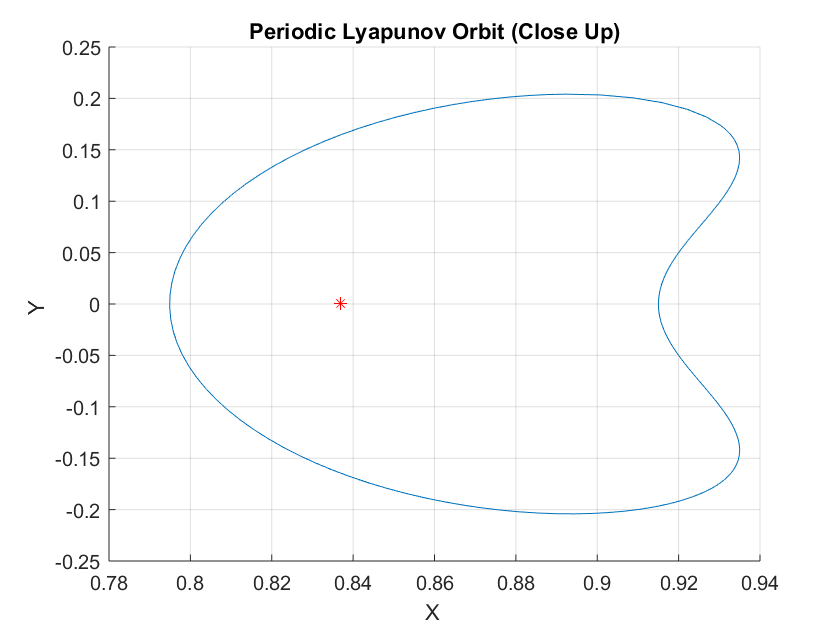

t_halfPeriod = 1.7521

X_newVy = 0.3877


[t_halfPeriod,X_newVy] = singleShootingLyapunovV1(mu,20,Xguess, Vy_guess,Ax,L1)


pdata.mu = mu

pdata = struct with fields:
    mu: 0.0122



STM = reshape(eye(4),16,[])';
Xguess = [Xguess 0 0 Vy_guess];
X0 = [Xguess STM]';


